# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

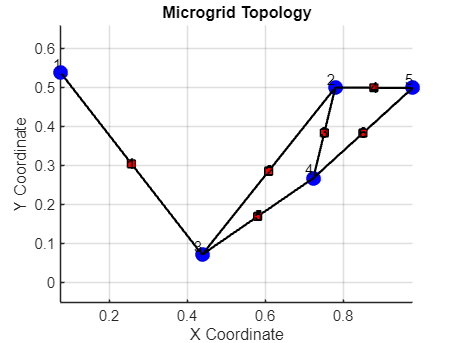

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0

B_il Matrix:
     1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1



% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold);


%%%% Update the figure to show the assumed initial communication topology
% (A_ij matrix representa the communication topology)



## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance
IL0 = 5;        % Constant Current Load


for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 % global DG Line B_il A_ij % Making some values as global variables

## Co-Design Process

parameters

BarGamma = 1;    % Fixed value for gammaBar
isSoft = 1;      % Set to 1 to avoid the hard graph constraint

% pScalar = 1/(numOfDGs+numOfLines);
piScalar = 0.0001;
plScalar = 1;

piVals = piScalar*ones(1,numOfDGs);
plVals = plScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

% Inside the function, you need to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

First Method: This Method computes the passivity indices for DGs and lines at the same time. 

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   0


Second Method: This method first computes the DGs' passivity indices and use those properties to compute the Lines' passivity indices. 

% [DG, rhoTilde_i, nu_i, gammaTilde_i,statusDG] = designDGPassivity(DG, B_il,piVals);
% [Line, statusLine] = designLinePassivity(Line, DG, B_il, BarGamma, piVals,plVals,rhoTilde_i, nu_i);
%%%% Theoretically explain why this works in the paper, in a corollary (of Theorem 2).  
%%%% There is an imbalance


DG{1}

ans = struct with fields:
              R: 0.0268
              L: 0.0180
              C: 0.0026
              Y: 3.3260
             IL: 5.0288
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.0763 0.5385]
             P0: [3×3 double]
             K0: [-4.7450e+03 -2.1320e+04 -1.1308e+04]
             nu: -1.5631e-14
            rho: -1.0409e+17
    gammaTilde0: 6.3250e-06


Line{1}

ans = struct with fields:
      R: 0.0284
      L: 0.0177
      A: -1.6046
      B: 56.5404
     P0: 3.7399e-15
     nu: 2.5850e-14
    rho: 2.6520e-13


## 2. Global Controller Design

% Initialized nominal and reference voltages
V_nom = 120;            % Nominal Voltage
V_ref = 48;             % Reference Voltage

% Scenario #1: Global Load Change
R_Global = 5;           % Global Load
ChangeGlobalLoad1 = 1;  % Connect Global Load #2
ChangeGlobalLoad2 = 3;  % Disconnect Global Load #2

% Scenario #2: Plug-and-Play 
PlugOut = 2;            % Plug out DG #4
PlugIn = 4;             % Plug in DG #4

% Scenario #3: Change of Reference Voltage:
V_ref1 = 48;
V_ref2 = 100;
change_reference = 4;

[DG,Line,statusGlobalController,gammaTildeVal,K,C,BarC,H,P_iVal,P_lVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft);
%%%% Theoretically think about adding cormalizing constraints trace(P_i)==1, trace(P_l)==1 constraint

K{1,1}

ans = 1.0e+17 *

         0         0         0
         0   -2.4821         0
         0         0         0


K{4,4}

ans = 1.0e+16 *

         0         0         0
         0   -5.9533         0
         0         0         0


#### The following functions are desgined to evaluate the effects of different parameters on the passivity indices of DGs and lines and their feasibilities

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()

Optimize pVals (Method 3)

% plotLocalControlDesign(DG, Line, B_il, BarGamma, numOfDGs, numOfLines);
% hold on
% plotGlobalControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
% hold on
plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);


Function to evaluate the effect of number of DGs and Threshold

% numDGsRange = 5:6;              % Example range for number of DGs
% thresholdRange = 0.1:0.1:1;     % Example range for threshold values
% pScalarRange = 0.01:0.01:10;    % Example range for pScalar values
% BarGamma = 5;                   % Fixed value for gammaBar
% isSoft = 1;                     % Set to 1 to use soft constraint
% 
% [numOfDGs, threshold] = evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);